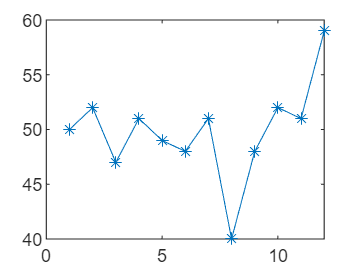

y = [50,52,47,51,49,48,51,40,48,52,51,59];
plot(y,'*-')

y=y';   %下面算标准误差时有用
n = length(y);
alpha = [0.2,0.5,0.8];
m = length(alpha);
yhat(1,1:m)= (y(1)+y(2))/2;
for i=2:n
    yhat(i,:)=alpha.*y(i-1)+(1-alpha).*yhat(i-1,:);
end
yhat

yhat =    51.0000   51.0000   51.0000
   50.8000   50.5000   50.2000
   51.0400   51.2500   51.6400
   50.2320   49.1250   47.9280
   50.3856   50.0625   50.3856
   50.1085   49.5312   49.2771
   49.6868   48.7656   48.2554
   49.9494   49.8828   50.4511
   47.9595   44.9414   42.0902
   47.9676   46.4707   46.8180


err = sqrt(mean((y-yhat).^2))   %算一列下来的标准误差，y要变成列向量

err =     4.5029    4.5908    4.8426


yhat1988= alpha.*y(n)+(1-alpha).*yhat(n,:)

yhat1988 =    51.1754   54.5588   57.3985



%alpha为0.2时标准误差较小选0.2